% incomplete due to missing spillage parameter in efficiency equation
clear
clc

%% load data
opts = spreadsheetImportOptions("NumVariables", 8);

% Specify sheet and range
opts.Sheet = "LA AFRICANA- TMY + dumped energ";
opts.DataRange = "A2:H52561";

% Specify column names and types
opts.VariableNames = ["DATEddmmaaaa", "DNIDirectnormalirradiationWm2", "SESunelevation", "SASunazimuth", "TEMPAirtemperature", "RHRelativehumidity", "WSWindspeed", "ThermalEnergyDumpedMW"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, "DATEddmmaaaa", "InputFormat", "");

% Import the data
LAAFRICANATMYdumpedenergy = readtable("C:\Users\Frank\Dropbox\uni work\Cranfield\applied thermal energy systems\applied thermal energy systems\LA AFRICANA- TMY + dumped energy.xlsx", opts, "UseExcel", false);

% select DNI, Azimuth and Altitude data
DNI = LAAFRICANATMYdumpedenergy.DNIDirectnormalirradiationWm2;
Azimuth = LAAFRICANATMYdumpedenergy.SASunazimuth;
Altitude = LAAFRICANATMYdumpedenergy.SESunelevation;


%% Calculate average hourly values for azimuth, altitude and DNI 

Hourly_DNI = zeros(24,365);
Hourly_Azimuth = zeros(24,365);
Hourly_Altitude = zeros(24,365);
time_in = 1;

for d = 1:365
    AvgHourDNI = zeros(1,24); % create matrix for the hours of the day to be put.
    AvgHourAzimuth = zeros(1,24);
    AvgHourAltitude = zeros(1,24);
    for i = 1:24
        countedDNI = zeros(1,6); % Create array so the time slots can be collected with an hour. 
        countedAzimuth = zeros(1,6);
        countedAltitude = zeros(1,6);
        for g = 1:6
            idx = time_in + (g - 1); % find location to index 
            countedDNI(g) = DNI(idx); % replace 0 with DNI at posititon idx
            countedAzimuth(g) = Azimuth(idx);
            countedAltitude(g) = Altitude(idx);
        end 
        AvgHourDNI(i) = mean(countedDNI); % Replace 0 with mean value of counted
        AvgHourAzimuth(i) = mean(countedAzimuth);
        AvgHourAltitude(i) = mean(countedAltitude);
        time_in = time_in + 6; % advance to the next hour        
    end
    Hourly_DNI(:,d) = AvgHourDNI; % place values for the hour in the year matrix
    Hourly_Azimuth(:,d) = AvgHourAzimuth;
    Hourly_Altitude(:,d) = AvgHourAltitude;    
end

% initialize calculate hourly values
AvgDNI = zeros(1,24);
AvgAzimuth = zeros(1,24);
AvgAltitude = zeros(1,24);

% calculate hourly values
for i = 1:24
    AvgDNI(i) = mean(Hourly_DNI(i,:));
    AvgAzimuth(i) = mean(Hourly_Azimuth(i,:));
    AvgAltitude(i) = mean(Hourly_Altitude(i,:));
end 

% Sunlight DNI, Azimuth and altitude values
AvgDNIlight = AvgDNI == 0; 
AvgDNI(AvgDNI == 0) = [];
AvgAzimuth(AvgDNIlight == 1) = [];
AvgAltitude(AvgDNIlight == 1) = [];

# Calculate thermal input into the receiver needed

% input values
Thermal_Storage_Hours = 15;
Power_output_electrical = 20*10^6;
Generator_eff = 0.4;
Resiver_eff = 0.8;
daylight_hours = 12;

% Thermal input into resiver 
Generator_in = Power_output_electrical / Generator_eff;
Total_storage = Thermal_Storage_Hours * Generator_in; % total energy storage (Wh)
To_Storage = Total_storage / daylight_hours; % how much energy needs to go to storage during daylight hours
From_resiver = Generator_in + To_Storage;
Resiver_input = From_resiver / Resiver_eff;



# Create large unoptimized field

Create oversized field to generate x and y cordinates for the optimization process

% Calculate power for over sized field
oversize = 2; % how much to oversize by
Power_oversized = Resiver_input * oversize;


There are 4 different zones which are called 1a, 1b, 2 and 3.

% initial values
Hw = 10; % heliostat width
Hh = 10; % heliostat hight
Harea = Hw*Hh;
Rmin = 75; % minimum radius for first row of mirrors
Ri = Rmin; % initial radius
Rclearance = 4; % Radial clearance to allow access for mirror cleaning equipment (m)
Smin = Hh + Rclearance; % Minimum radial spacing between heliostat rows (m)
Cclearance = 1; % Circumferential mechanical safety clearance (m)
Cmin = Hw + Cclearance; % minimum circumferential spacing between heliostats (m)
Heliostat_hight = 20;
Tower_hight = 150;
Rh = Tower_hight - Heliostat_hight;
[DNImax, idx] = max(AvgDNI);
Azimuth_max = AvgAzimuth(idx);
Altitude_max = AvgAltitude(idx);
power_produced = 0;
radius = 75; % created for saving the radius values of the rows for use in optimization

while power_produced < Power_oversized % sets when calculations can stop 
    

zone 1

% Zone 1a first row
    % Calculate number of heliostats and angle between
    [No_Helio,DelTheta] = Number_Helios_and_Theta(Ri,Cmin);
    
    % Calculate x and y cordinates
    [d,e] = Rotation_matrix(No_Helio,DelTheta,Ri);
    x = d;
    y = e;
    
    % Calculate power produced
    [power_produced, eff] = Power_produced_first_row(d,e,Rh,Altitude_max,Azimuth_max,power_produced,DNImax,Harea,Ri);
    
    % Radius of next row
    Ri = Ri + Smin;
    radius = [radius Ri]; % store radius values
    % calculate Sblock
    [Sblock] = CalcSblock(Ri,Rh,Hh);
    
% Zone 1a rest
while Sblock<2*Smin
    if Sblock < Smin        
        % Calculate number of heliostats and angle between
        [No_Helio,DelTheta] = Number_Helios_and_Theta(Ri,Cmin);
    
        % Calculate x and y cordinates
        [d,e] = Rotation_matrix(No_Helio,DelTheta,Ri);
        x = [x d];
        y = [y e];
        
        % Calculate power produced
        [power_produced, eff] = Power_produced(d,e,Rh,Altitude_max,Azimuth_max,power_produced,DNImax,eff,Harea,Ri);
                        
        % Radius of next row
        Ri = Ri + Smin;
        radius = [radius Ri];
        
        % calculate Sblock
        [Sblock] = CalcSblock(Ri,Rh,Hh);

% Zone 1b
    elseif Sblock < 2*Smin        
        % Calculate number of heliostats and angle between
        [No_Helio,DelTheta] = Number_Helios_and_Theta(Ri,Cmin);
    
        % Calculate x and y cordinates
        [d,e] = Rotation_matrix(No_Helio,DelTheta,Ri);
        x = [x d];
        y = [y e];
        
        % Calculate power produced
        [power_produced, eff] = Power_produced(d,e,Rh,Altitude_max,Azimuth_max,power_produced,DNImax,eff,Harea,Ri);
                        
        % Radius of next row
        Ri = Ri + Sblock;
        radius = [radius Ri];
        
        % calculate Sblock
        [Sblock] = CalcSblock(Ri,Rh,Hh);
    end
end
    
    

Zone 2

row = 1;
Cord_length = 2*Ri*sind(DelTheta/2);
while Cord_length < 4*Hw % when zone 2 stops
    if row == 1 % first row of zone 2 calculations
         
        %set radius for calculation of number of heliostats
        Rzone2 = Ri; 
                
        % calculate number of heliostats and angle for zone2
        [No_Helio,DelTheta] = Number_Helios_and_Theta_Zone2(Rzone2,Hw);
                
        % calculate positions
        [d,e] = Rotation_matrix(No_Helio,DelTheta,Ri);
        x = [x d];
        y = [y e];
        
        % Calculate power produced
        [power_produced, eff] = Power_produced(d,e,Rh,Altitude_max,Azimuth_max,power_produced,DNImax,eff,Harea,Ri);
                
        % Radius of next row
        Ri = Ri + Sblock/2;
        radius = [radius Ri];
        
        % calculate Sblock and cord length
        [Sblock] = CalcSblock(Ri,Rh,Hh);
        Cord_length = 2*Ri*sind(DelTheta/2);
        
        % set row number 
        row = row +1;
    
    elseif row > 1 % calculations for after first row of zone 2
        remainder = rem(row,2);
        
        if remainder == 0 % section with offset
           
            % calculate positions of x and y with offset
            [d,e] = Rotation_matrix_Zone2_even_row(No_Helio,DelTheta,Ri);
            x = [x d];
            y = [y e];
            
            % Calculate power produced
            [power_produced, eff] = Power_produced(d,e,Rh,Altitude_max,Azimuth_max,power_produced,DNImax,eff,Harea,Ri);
            
            % Radius of next row
            Ri = Ri + Sblock/2;
            radius = [radius Ri];
            
            % calculate Sblock and cord length
            [Sblock] = CalcSblock(Ri,Rh,Hh);
            Cord_length = 2*Ri*sind(DelTheta/2);
            
            % set row number 
            row = row +1;
        else % section with no offset
            
            % calculate positions
            [d,e] = Rotation_matrix(No_Helio,DelTheta,Ri);
            x = [x d];
            y = [y e];
            
            % Calculate power produced
            [power_produced, eff] = Power_produced(d,e,Rh,Altitude_max,Azimuth_max,power_produced,DNImax,eff,Harea,Ri);
                    
            % Radius of next row
            Ri = Ri + Sblock/2;
            radius = [radius Ri];
            
            % calculate Sblock and cord length
            [Sblock] = CalcSblock(Ri,Rh,Hh);
            Cord_length = 2*Ri*sind(DelTheta/2);
            
            % set row number 
            row = row +1;
           
        end
    end
end


Zone 3

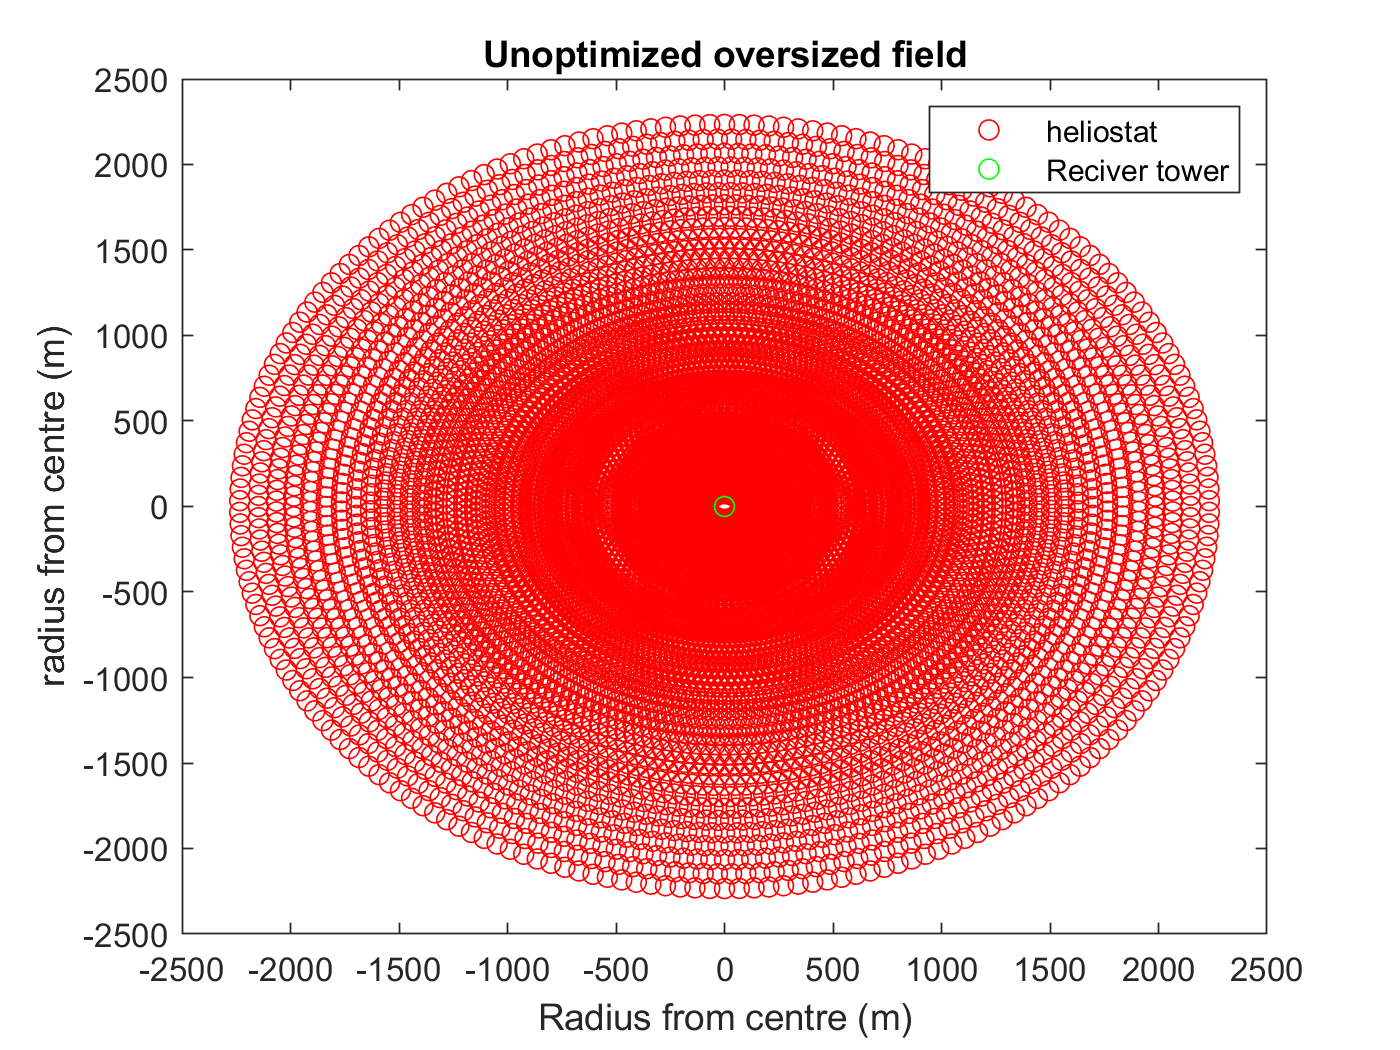

% zone 3 values
No_Helio = 2*No_Helio;
DelThetaZone3 = DelTheta / 2;
row = 1;
   
    % calculate positions
    [d,e] = Rotation_matrix_Zone3_With_offset(No_Helio,DelTheta,DelThetaZone3,Ri);
    x = [x d];
    y = [y e];
    
    % Calculate power produced
    [power_produced, eff] = Power_produced(d,e,Rh,Altitude_max,Azimuth_max,power_produced,DNImax,eff,Harea,Ri);
                
    % Radius of next row
    Ri = Ri + Sblock/2;
    radius = [radius Ri];
    
    % calculate Sblock and cord length
    [Sblock] = CalcSblock(Ri,Rh,Hh);
    Cord_length = 2*Ri*sind(DelThetaZone3/2);
    
    % set row number 
    row = row +1;

% finish off the field untill power_oversized is met
while power_produced <= Power_oversized
    if rem(row,2)==0
       
        % create positions
        [d,e] = Rotation_matrix(No_Helio,DelThetaZone3,Ri); 
        x = [x d];
        y = [y e];
        
        % Calculate power produced
        [power_produced, eff] = Power_produced(d,e,Rh,Altitude_max,Azimuth_max,power_produced,DNImax,eff,Harea,Ri);
        
        % Radius of next row
        Ri = Ri + Sblock/2;
        radius = [radius Ri];
        
        % calculate Sblock and cord length
        [Sblock] = CalcSblock(Ri,Rh,Hh);
        Cord_length = 2*Ri*sind(DelThetaZone3/2);
        
        % set row number 
        row = row +1;
        
    else
        % calculate positions
        [d,e] = Rotation_matrix_Zone3_With_offset(No_Helio,DelTheta,DelThetaZone3,Ri);
        x = [x d];
        y = [y e];
        
        % Calculate power produced
        [power_produced, eff] = Power_produced(d,e,Rh,Altitude_max,Azimuth_max,power_produced,DNImax,eff,Harea,Ri);
                    
        % Radius of next row
        Ri = Ri + Sblock/2;
        radius = [radius Ri];
        
        % calculate Sblock and cord length
        [Sblock] = CalcSblock(Ri,Rh,Hh);
        Cord_length = 2*Ri*sind(DelThetaZone3/2);
        
        % set row number 
        row = row +1; 
    end
end
end

% plot unoptimized field 
figure(1)
plot(x,y,'ro')
title('Unoptimized oversized field')
xlabel('Radius from centre (m)')
ylabel('radius from centre (m)')
hold on
plot(0,0,'go')
legend('heliostat','Reciver tower','location',"northeast")

# Optimize solar field

This uses the x and y cordinates to recalculate the efficencies of the heliostats and then finds the value of the max power. The user is then asked to input a value for how much of the max value you want to have as the cut off point under which no further contributions are considered. All heliostats below this point are then deleted

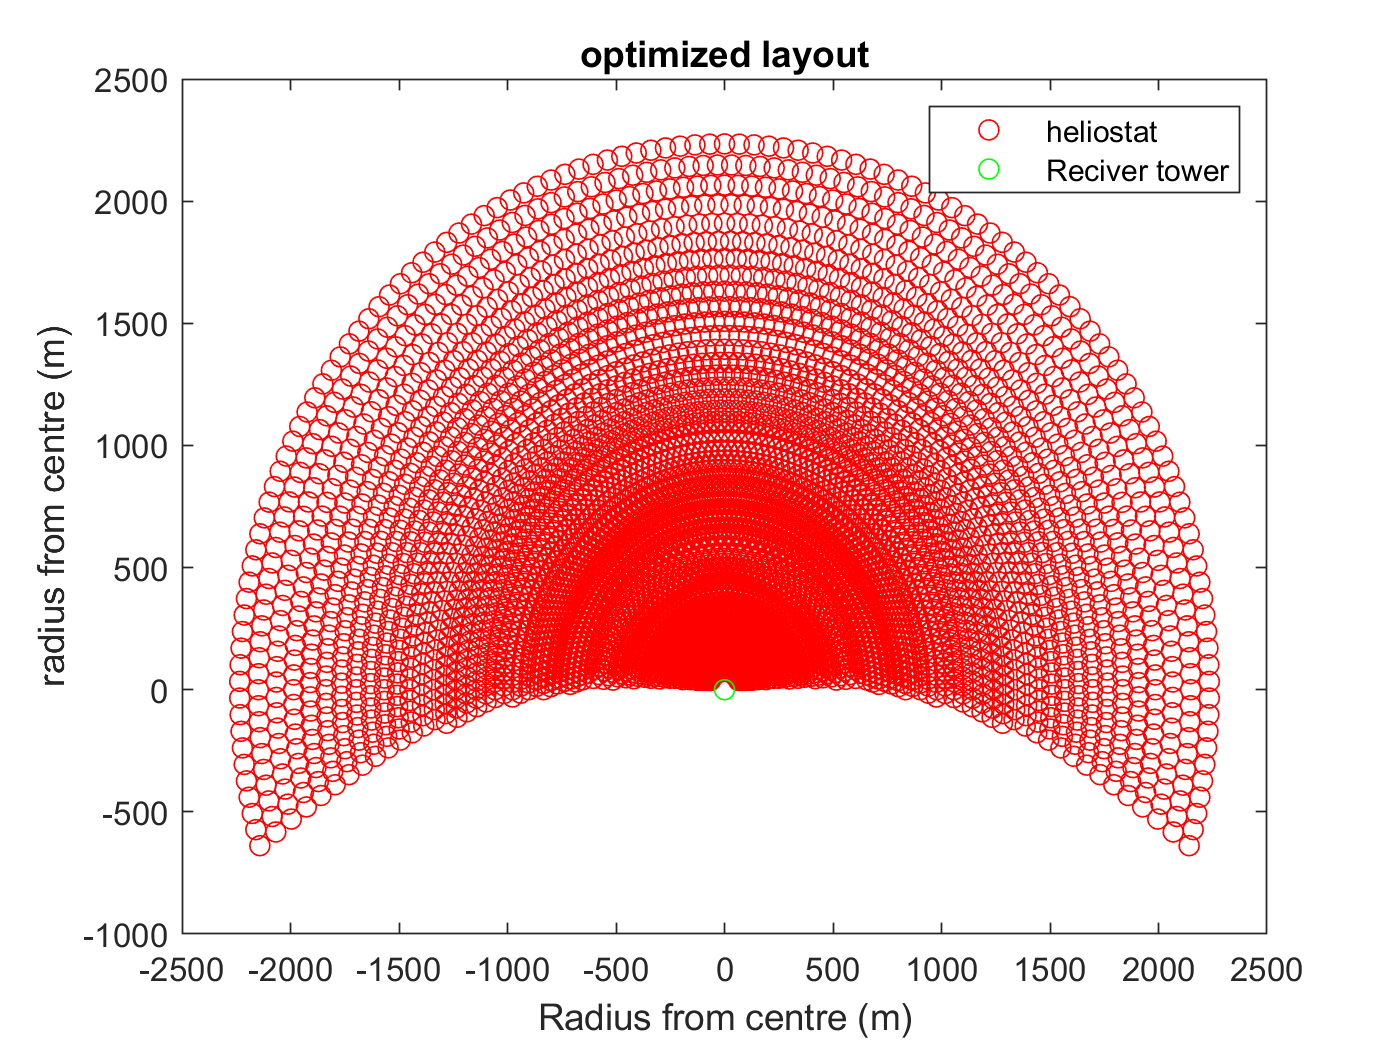

% calculate power produced by each heliostat for each hour of daylight
power_supplied = zeros(length(AvgDNI),length(x));
efficency = zeros(length(AvgDNI),length(x));
for i = 1:length(AvgDNI)    
    [efficency(i,:)] = efficencyend(x,y,Rh,AvgAltitude(i),AvgAzimuth(i),radius);
    power_supplied(i,:) = AvgDNI(i) .* efficency(i,:) .* Harea;
end

Total_power_per_heliostat = sum(power_supplied); % total power that is produced by the heliostat over the day

% find level of power production you will stop looking for new heliostats 
percent_decimal = input('What percentage of the power from the maximum total power do you want to stop selecting new heliostats in decimal form ie 20% = 0.2'); % select 0.65
stop_select = max(Total_power_per_heliostat) * percent_decimal;

selected_heliostats = Total_power_per_heliostat >= stop_select;
x(selected_heliostats == 0) = [];
y(selected_heliostats == 0) = [];

figure(2)
plot(x,y,'ro')
title('optimized layout')
xlabel('Radius from centre (m)')
ylabel('radius from centre (m)')
hold on
plot(0,0,'go')
legend('heliostat','Reciver tower','location',"northeast")

# Annual performance assessment 

Thermal power dilevered to resiever through out the year

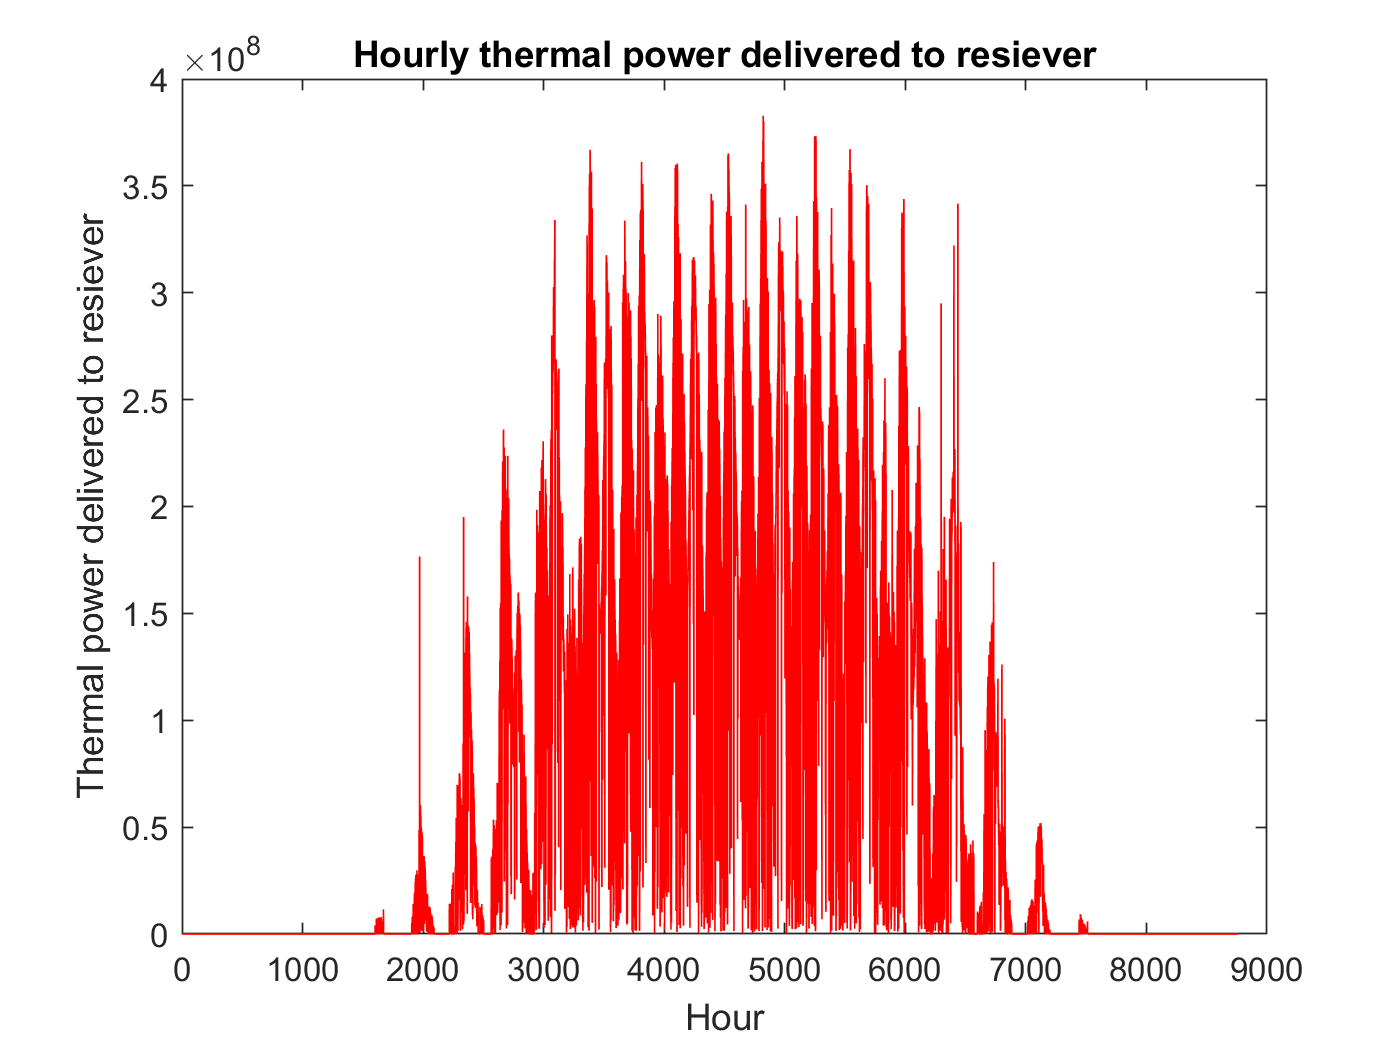

Hourly_DNI = reshape(Hourly_DNI',1,[]);
Total_Thermal = zeros(length(x),24*365);
efficency = zeros(length(x),24*365);
for i = 1:24*365    
    [efficency(:,i)] = efficencyend(x,y,Rh,Altitude(i),Azimuth(i),radius);
    Total_Thermal(:,i) = Hourly_DNI(i) .* efficency(:,i) .* Harea;    
end
Total_Thermal = sum(Total_Thermal);

figure(3)
plot(1:24*365,Total_Thermal,'r-')
title('Hourly thermal power delivered to resiever')
xlabel('Hour')
ylabel('Thermal power delivered to resiever')